# Turbulent sensible heat flux in isothermal layer

A key conclusion of the sublimation study (Cox et al., submitted) is that warm regime turbulent heat transfer within a sublayer. Ultimately, the transfer is likely molecular within a nested interfacial layer. However, the observed sublayer is deeper than Kolmogorov scales, so eddy diffusion helps evolve it, but it is still quite shallow (10s cm). Abover the layer, the temperature profile is approximately isothermal. The April 18-19 case study, for example, had a constant θ profile from the 16 cm above to surface to 3 km height. The sonic anemometers from SPLASH and SOS both independently measured large turbulent heat fluxes within the isothermal layer. Indeed, the latent heat fluxes were strongly divergent in the lowest 20 m (Schwat et al., submitted), which I interpret to be consistent with dilution of vapor transferred within in the sublayer as it is mixed upwards. 

However, the question remains, how do we explain the turbulent heat fluxes in the isothermal layer? 

Noting that latent and sensible heat flux are additive inverses for the case study, the hypotheses for sensible heat flux are as follows:

(a) There is a recognizable turbulence co-spectrum of  during the case study, observable in 

(a) The distirubtion of T_acoustic at some height above the sublayer has a mean value equal to the isothermal layer, but is distributed with a skew towards colder values with the heavy side covariant with +w'. 

(b) The variance in T_acoustic is larger close to the surface and gets smaller with increasing disttance from the surface, explaining the divergence.

References:

Cox, C. J., Adler, B., Butterworth, B. J., and Schwat, E. (submitted). Processes modulating snowpack sublimation after peak storage in the East River Valley of Colorado: Application of surface renewal theory. *Journal of Geophysical Research - Atmospheres*.

Schwat, E., Hogan, F., U, K. T. P., Cox, C. J., Butterworth, B. J., Gutmann, E., Vano, J. A., & Lundquist, J. E. (submitted). Vertical divergence of eddy covariance water vapor flux measurements over snow-covered complex terrain. *Journal of Hydrometeorology.*

## Get data

(1) Directories and load for ASFS-50

data_dir = '/Users/ccox/Documents/Projects/2021/splash/science/sublimation/sos_case_study/sos_data/';
cd(data_dir);
load('/Users/ccox/Documents/Projects/2021/splash/_level2/a50dbl.mat')
a50 = data10;

(2) Some prereuisites

Use 23:00 UTC hour (17:00 local) as a late-afternoon sample for each day in 2023 from February 1 - April 30. 

Evaluate data at heights above soil of 2, 3, 5 ,1, 15, 20 m. Heights above snow surface is less. Being quite approximate, use the value of snow depth for the April 18 case study to adjust the heights (0.84 m). 

days = [1:28 1:31 1:30]; % refers to March 1 - April 30
hts = [2, 3, 5, 10, 15, 20]-0.84; % height vector
bins = -3:0.01:3; % for the distributions of temperature and wind anomalies
indcase = 77; % the April 18 case study, e.g., Figure 7.

(3) Collect data from each day for each height for both acoustic temperature (tc) and vertical wind fluctuations (w), as well as some data about thermodynamic temperatures:

- Identify the 10 m and 3 m mean hourly temperatures and there mean differences. 

- Store variances in tc and w.

- Store histograms of tc and w.

Ta = NaN(length(days),1);
dT = NaN(length(days),1);
varstc = NaN(length(days),length(hts));
varsw = NaN(length(days),length(hts));
binstc = NaN(length(days),length(bins),length(hts));
binsw = NaN(length(days),length(bins),length(hts));
for j = 1:length(days)
    
    % Load the file
    theday = num2str(days(j));
    if isscalar(theday); theday = ['0',theday]; end
    if j <= 28
        file = rd_netcdf(['isfs_sos_qc_geo_tiltcor_hr_202302',theday,'_23.nc'],'tc_2m_c','tc_3m_c','tc_5m_c','tc_10m_c', ...
        'tc_15m_c','tc_20m_c','w_2m_c','w_3m_c','w_5m_c','w_10m_c','w_15m_c','w_20m_c','T_10m_c','T_5m_c');
    elseif j > 28 & j <= 59
        file = rd_netcdf(['isfs_sos_qc_geo_tiltcor_hr_202303',theday,'_23.nc'],'tc_2m_c','tc_3m_c','tc_5m_c','tc_10m_c', ...
        'tc_15m_c','tc_20m_c','w_2m_c','w_3m_c','w_5m_c','w_10m_c','w_15m_c','w_20m_c','T_10m_c','T_5m_c');
    else
        file = rd_netcdf(['isfs_sos_qc_geo_tiltcor_hr_202304',theday,'_23.nc'],'tc_2m_c','tc_3m_c','tc_5m_c','tc_10m_c', ...
        'tc_15m_c','tc_20m_c','w_2m_c','w_3m_c','w_5m_c','w_10m_c','w_15m_c','w_20m_c','T_10m_c','T_5m_c');
    end

    % Replace QC'd values with NaN 
    file.T_10m_c(file.T_10m_c > 1e6) = NaN;
    file.T_5m_c(file.T_5m_c > 1e6) = NaN;
    file.tc_2m_c(file.tc_2m_c > 1e6) = NaN;
    file.tc_3m_c(file.tc_3m_c > 1e6) = NaN;
    file.tc_5m_c(file.tc_5m_c > 1e6) = NaN;
    file.tc_10m_c(file.tc_10m_c > 1e6) = NaN;
    file.tc_15m_c(file.tc_15m_c > 1e6) = NaN;
    file.tc_20m_c(file.tc_20m_c > 1e6) = NaN;
    file.w_2m_c(file.w_2m_c > 1e6) = NaN;
    file.w_3m_c(file.w_3m_c > 1e6) = NaN;
    file.w_5m_c(file.w_5m_c > 1e6) = NaN;
    file.w_10m_c(file.w_10m_c > 1e6) = NaN;
    file.w_15m_c(file.w_15m_c > 1e6) = NaN;
    file.w_20m_c(file.w_20m_c > 1e6) = NaN;
    
    % We have to reshape because the 20 Hz data is stored as (Hz,Sec) or (20,3600) for hour blocks
    data1.tc2 = file.tc_2m_c; data1.tc2 = reshape(data1.tc2,20*3600,1);
    data1.tc3 = file.tc_3m_c; data1.tc3 = reshape(data1.tc3,20*3600,1);
    data1.tc5 = file.tc_5m_c; data1.tc5 = reshape(data1.tc5,20*3600,1);
    data1.tc10 = file.tc_10m_c; data1.tc10 = reshape(data1.tc10,20*3600,1);
    data1.tc15 = file.tc_15m_c; data1.tc15 = reshape(data1.tc15,20*3600,1);
    data1.tc20 = file.tc_20m_c; data1.tc20 = reshape(data1.tc20,20*3600,1);
    data1.w2 = file.w_2m_c; data1.w2 = reshape(data1.w2,20*3600,1);
    data1.w3 = file.w_3m_c; data1.w3 = reshape(data1.w3,20*3600,1);
    data1.w5 = file.w_5m_c; data1.w5 = reshape(data1.w5,20*3600,1);
    data1.w10 = file.w_10m_c; data1.w10 = reshape(data1.w10,20*3600,1);
    data1.w15 = file.w_15m_c; data1.w15 = reshape(data1.w15,20*3600,1);
    data1.w20 = file.w_20m_c; data1.w20 = reshape(data1.w20,20*3600,1);

    % At each height
    %   - calculate the variances in acoustic temperature (tc')
    %   - calculate the variances in vertical wind component (w')
    % I will center them using the median because tc calibrations usually vary amongst sonic sensors.
    thevarstc = [var(data1.tc2-median(data1.tc2,'omitnan'),'omitnan') ...
     var(data1.tc3-median(data1.tc3,'omitnan'),'omitnan') ...
     var(data1.tc5-median(data1.tc5,'omitnan'),'omitnan') ...   
     var(data1.tc10-median(data1.tc10,'omitnan'),'omitnan') ...
     var(data1.tc15-median(data1.tc15,'omitnan'),'omitnan') ...
     var(data1.tc20-median(data1.tc20,'omitnan'),'omitnan')];
    varstc(j,:) = thevarstc;

    thevarsw = [var(data1.w2-median(data1.w2,'omitnan'),'omitnan') ...
     var(data1.w3-median(data1.w3,'omitnan'),'omitnan') ...
     var(data1.w5-median(data1.w5,'omitnan'),'omitnan') ...   
     var(data1.w10-median(data1.w10,'omitnan'),'omitnan') ...
     var(data1.w15-median(data1.w15,'omitnan'),'omitnan') ...
     var(data1.w20-median(data1.w20,'omitnan'),'omitnan')];
    varsw(j,:) = thevarsw;

    % We will plot historgrams later. Instead of saving the raw data, save
    % the binned data.
    binstc(j,:,1) = histcounts(data1.tc2-median(data1.tc2,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binstc(j,:,2) = histcounts(data1.tc3-median(data1.tc3,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binstc(j,:,3) = histcounts(data1.tc5-median(data1.tc5,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binstc(j,:,4) = histcounts(data1.tc10-median(data1.tc10,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binstc(j,:,5) = histcounts(data1.tc15-median(data1.tc15,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binstc(j,:,6) = histcounts(data1.tc20-median(data1.tc20,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binsw(j,:,1) = histcounts(data1.w2-median(data1.w2,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binsw(j,:,2) = histcounts(data1.w3-median(data1.w3,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binsw(j,:,3) = histcounts(data1.w5-median(data1.w5,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binsw(j,:,4) = histcounts(data1.w10-median(data1.w10,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binsw(j,:,5) = histcounts(data1.w15-median(data1.w15,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');
    binsw(j,:,6) = histcounts(data1.w20-median(data1.w20,'omitnan'),[bins bins(end)+mode(diff(bins))],'Normalization','probability');

    % Store means
    Ta(j) = mean(file.T_10m_c,'omitnan');
    dT(j) = mean(file.T_10m_c-file.T_5m_c,'omitnan');
    
    if j == 1; fprintf(1,'Data Loading Progress: %3d%%\n',0); else; fprintf(1,'\b\b\b\b%3.0f%%',j/length(days)*100); end
end

Data Loading Progress:  100%

## Plot 1. Co-spectra during the April 18 warm regime case

We observed a flux in the isothermal layer during the April 18 case. I will plot the data from the the ASFS-50 at Avery Picnic as an average of the 36 ten-minute integration periods over 6-hours centered on the 17:29 local radiosonding (paper Figure 7). The mean sensible heat flux was -40 W m^-2 and the latent heat flux was +57 Wm^-2. The shape of the co-spectra look reasonable, though peaking at somewhat longer time scales than expected (~ 1 min), which could be overturning from vortex shedding thought to be influential on that day.

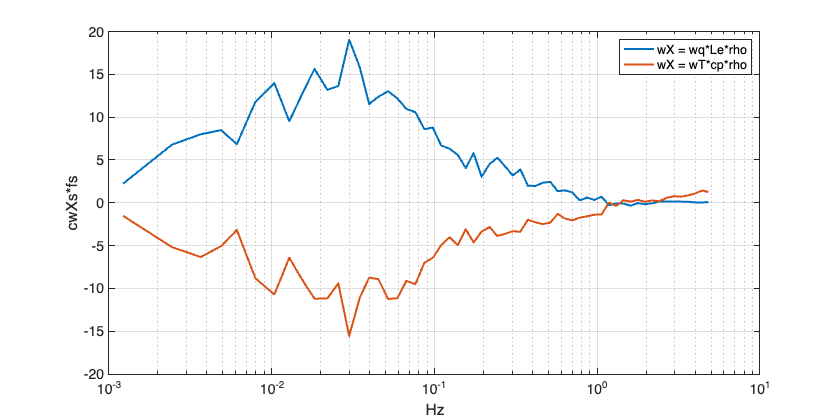

ind50 = find(a50.dn >= datenum([2023 4 18 23 29 0])-3/24 & a50.dn <= datenum([2023 4 18 23 29 0])+3/24);

% some approximations for the plot. the actual calculation does a bit more
% the purpose here is to scale the spectra to show how they compensate for one another
rho = 0.88; % air density
Le = (2.501-.00237*7.5)*1e6; % latent heat of vaporization
cp = 1005; % heat capacity of air

fig1 = figure(); 
plot(a50.fs,mean(a50.cWqs(:,ind50),2).*a50.fs.*Le.*rho,'linewidth',2); hold on;
plot(a50.fs,mean(a50.cWTs(:,ind50),2).*a50.fs.*cp.*rho,'linewidth',2);
set(gca,'xscale','log','yscale','lin');
xlabel('Hz'); ylabel('cwXs*fs'); grid on;
set(gca,'fontsize',14);
legend('wX = wq*Le*rho','wX = wT*cp*rho');
fig1.Position(3) = fig1.Position(3)*1.5;

disp(['Sensible heat flux: ',num2str(mean(a50.Hs(ind50))),'W m^-^2']);

Sensible heat flux: -40.2649W m^-^2


disp(['Latent heat flux: ',num2str(mean(a50.Hl(ind50))),'W m^-^2']);

Latent heat flux: 56.8735W m^-^2


## Plot 2. normalized variance f(height)

By normalized variance, we mean that the varianve calculated at each height for each profile will be normalized by the value at the surface (for tc) and the value at the 20 m (for w). A similar result would be achieved if we normalized by the maximum value in the profile. The results for the left panel show that for acoustic temperature, the variance as a function of height can increase, decrease, or remain about the same. For the cold regime (cyan), any of these possibilities applies and in the mean the variance in unrelatedto height. Conversely, for the warm regime, there is high likelihood that the variance is large near the surface and decreases with height. In fact, the variance at 20 m is about 20% of the variance at 2 m for the warm regime. If we look at fluctuations in the vertical wind component instead (right panel), for all cases it is typical for the variance at 2 m to be about 20% of the variance at 20 m, which is consistent with the standard interpretation of surface friction on wind. The April 18, 2023 case study is a typical example for the warm regime.

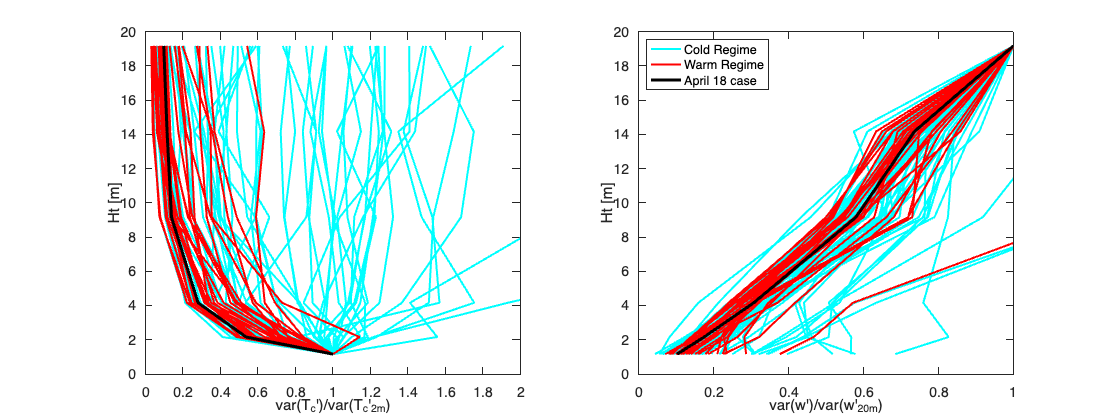

fig2 = figure(); 
subplot(1,2,1)
proftc = varstc./varstc(:,1);
ind = find((Ta) < 0);
plot(proftc(ind,:),hts,'c','linewidth',2); hold on;
ind = find((Ta) > 0);
plot(proftc(ind,:),hts,'r','linewidth',2);
plot(proftc(indcase,:),hts,'k','linewidth',3);
xlim([0 2]);
xlabel('var(T_c'')/var(T_c''_2_m)'); ylabel('Ht [m]');
set(gca,'fontsize',14,'xtick',0:0.2:2);
subplot(1,2,2)
profw = varsw./varsw(:,end);
ind = find((Ta) < 0);
h1=plot(profw(ind,:),hts,'c','linewidth',2); hold on;
ind = find((Ta) > 0);
h2=plot(profw(ind,:),hts,'r','linewidth',2);
h3=plot(profw(indcase,:),hts,'k','linewidth',3);
xlim([0 1]);
xlabel('var(w'')/var(w''_2_0_m)'); ylabel('Ht [m]');
legend([h1(1) h2(1) h3],'Cold Regime','Warm Regime','April 18 case','location','northwest');
set(gca,'fontsize',14); 
fig2.Position(3) = fig2.Position(3)*2;

## Plot 3. Histograms

The histograms show how the measurements are distrbuted during the 4/18 case study. The top panel is acoustic temperature. The higher variance expected near the surface is due to skew towards cold values, as expected. This skew is reduced farther above the surface.  

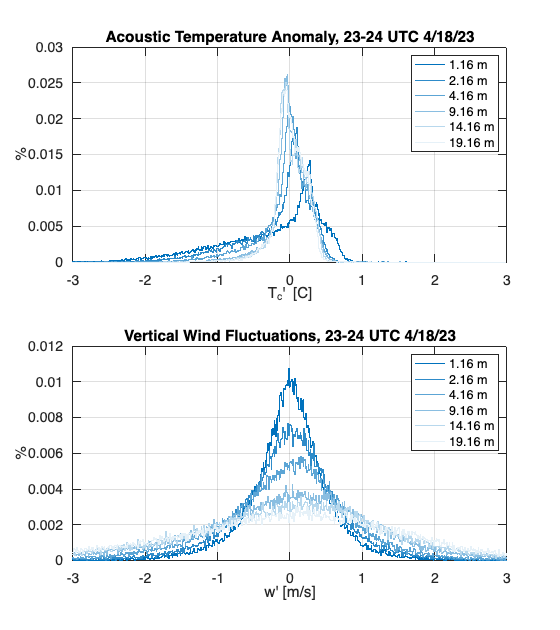

fig3 = figure(); 
cmapb = flipud(colormap(sky(6)));
subplot(2,1,1)
stairs(bins,binstc(77,:,1),'color',cmapb(1,:)); hold on;
stairs(bins,binstc(77,:,2),'color',cmapb(2,:));
stairs(bins,binstc(77,:,3),'color',cmapb(3,:));
stairs(bins,binstc(77,:,4),'color',cmapb(4,:));
stairs(bins,binstc(77,:,5),'color',cmapb(5,:));
stairs(bins,binstc(77,:,6),'color',cmapb(6,:));
xlabel('T_c'' [C]'); ylabel('%');
set(gca,'fontsize',14);  box on; grid on;
title('Acoustic Temperature Anomaly, 23-24 UTC 4/18/23');
leg=cell(6,1); for k = 1:6; leg{k}=[num2str(hts(k)),' m']; end; legend(leg);
subplot(2,1,2)
stairs(bins,binsw(77,:,1),'color',cmapb(1,:)); hold on;
stairs(bins,binsw(77,:,2),'color',cmapb(2,:));
stairs(bins,binsw(77,:,3),'color',cmapb(3,:));
stairs(bins,binsw(77,:,4),'color',cmapb(4,:));
stairs(bins,binsw(77,:,5),'color',cmapb(5,:));
stairs(bins,binsw(77,:,6),'color',cmapb(6,:));
xlabel('w'' [m/s]'); ylabel('%'); 
set(gca,'fontsize',14); box on; grid on;
title('Vertical Wind Fluctuations, 23-24 UTC 4/18/23');
leg=cell(6,1); for k = 1:6; leg{k}=[num2str(hts(k)),' m']; end; legend(leg);
fig3.Position(4) = fig3.Position(4)*1.5;